# Computational Mathematics

#        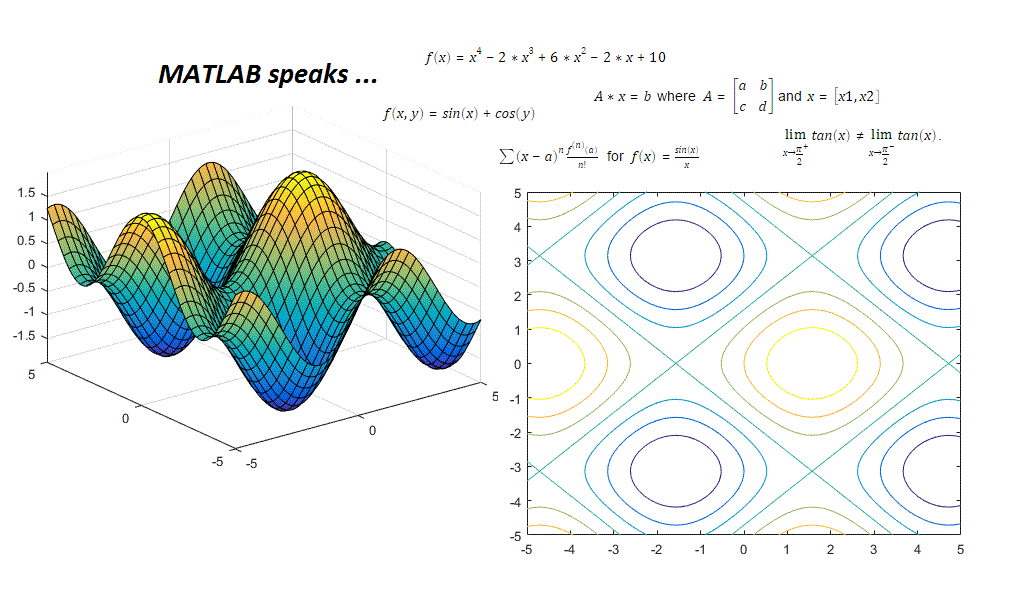

For more details see [Getting Started with Symbolic Math Toolbox](http://www.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html).  For more details on documenting and sharing your mathematics see [Create Live Scripts](http://www-jobarchive.mathworks.com/Bdoc16a/latest_pass/matlab/help/matlab/matlab_prog/create-live-scripts.html).

## Variables, expressions, functions and equations

The Symbolic Math Toolbox supports [mathematical expressions, functions and equations](http://www.mathworks.com/help/symbolic/mathematical-functions.html).  It supports a wide breadth of functions including trigonometric, logarithmic, exponential, and special functions. 

Express numbers in exact rational form instead of decimal approximations. 

sym(pi/6) + sym(pi/4)

$$ans = \frac{5\,\pi }{12}$$

pi/6 + pi/4

ans = 1.3090

Create symbolic variables, vectors and matrices using [sym](http://www.mathworks.com/help/symbolic/sym.html). Create symbolic expressions and perform mathematical calculations.

syms x y 
log(x) + exp(y)

$$ans = {\mathrm{e}}^{y}+\log\left(x\right)$$

Create and evaluate [functions](http://www.mathworks.com/help/symbolic/create-symbolic-functions.html), find the value of $f(x) = x^4-2*x^3+6*x^2-2*x+10$ at $x = -5$.  

syms f(x)
f(x) = x^4-2*x^3+6*x^2-2*x+9

$$f(x) = x^{4}-2\,x^{3}+6\,x^{2}-2\,x+9$$

f(-5)

$$ans = 1044$$

Create equations using the == operator; find the intersection between lines $y1
$ and $y2$ using [solve](http://www.mathworks.com/help/symbolic/solve.html).

syms y1 y2
y1 = x+3; y2 = 2.6 *x;
solve(y1 == y2)

$$ans = \frac{15}{8}$$

Confirm empty-set result graphically:

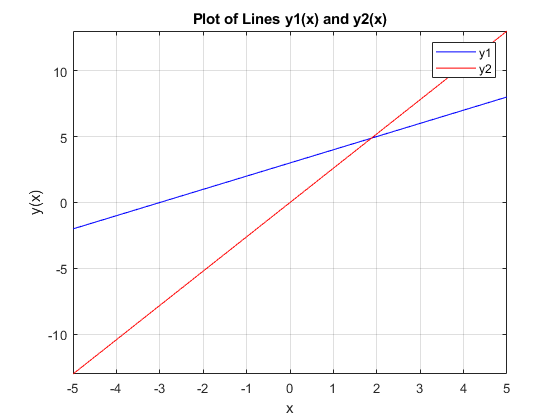

fplot(y1,'b');grid on; hold on
fplot(y2,'r');
title('Plot of Lines y1(x) and y2(x)')
xlabel('x')
ylabel('y(x)')
legend('y1','y2')
hold off

Make [assumptions](http://www.mathworks.com/help/symbolic/assume.html) on symbolic variables. There are 4 solutions to $x^4=1$, two real and two complex.  Assuming that x is real and $x > 0 $ there is only one solution.

syms x b
assume(b>0)
solve(x^4 == b)

$$ans = \left(\begin{array}{c} -b^{1/4}\\ -b^{1/4}\,\mathrm{i}\\ b^{1/4}\,\mathrm{i}\\ b^{1/4} \end{array}\right)$$

assume(x,'real')
assumeAlso( x > 0)
assumptions(x)

$$ans = \left(\begin{array}{cc} x\in \mathbb{R} & 0<x \end{array}\right)$$

solve(x^4 == 1)

$$ans = 1$$

assume(x,'clear')

## Substitution and Solving

The Symbolic Math Toolbox supports evaluation of mathematical functions by substituting for any part of an expression using [subs](http://www.mathworks.com/help/symbolic/subs.html#zmw57dd0e114230). You can substitute numeric values, other symbolic variables or expressions, vectors, or matrices. The Symbolic Math Toolbox supports the solving of equations and systems of equations using [solve](http://www.mathworks.com/help/symbolic/solve.html).  It supports solving multi-variate equations, solving inequalities and solving with assumptions. Solutions can be found symbolically or numerically with high precision variable precision arithmetic. 

Make substitutions with your symbolic variables;  substitute $x = xo - 1$ into $x^2 + 1$ 

syms x xo
subs(x^2+1,x,xo-1)

Substitute multiple values, evaluate $cos(a) + sin(b) - e^{2C}$ by substituting  $a = \frac{\pi }{2}, b = \frac{\pi }{4}, c =-1$.

syms a b c
subs(cos(a) + sin(b) - exp(2*c), [a b c], [pi/2 pi/4 -1])

Create and solve equations; Find the zeros of $9x^2-1 = 0$.

solve(9*x^2 - 1 == 0)

Or solve the general quadratic equation $ax^2 + bx + c = 0$ and use subs to evaluate that solution for $a =9, b = 0, c =-1$.

eqn = a*x^2 + b*x + c == 0;
sol = solve(eqn) 
subs(sol,[a b c],[9 0 -1])

Solve equations numerically using variable precision arithmetic when high accuracy or speed is required.

syms f(x)
f(x) = 6*x^7-2*x^6+3*x^3-8;
sol = vpasolve(f)

## Simplification and Manipulation

The Symbolic Math Toolbox supports the [simplification and manipulation](http://www.mathworks.com/help/symbolic/formula-manipulation-and-simplification.html) of mathematical functions. Most mathematical expressions can be represented in different, but mathematically equivalent forms and the Symbolic Math Toolbox supports a number of operations including factoring or expanding expressions, combining terms, rewriting or rearranging expressions and simplification based on assumptions. 

Perform polynomial multiplication and simplify the results, show that $(x - 1)*(x + 1)*(x^2 + x + 1)*(x^2 + 1)*(x^2 - x + 1)*(x^4 - x^2 + 1)$ simplifies to $x^{12}-1$

simplify((x - 1)*(x + 1)*(x^2 + x + 1)*(x^2 + 1)*(x^2 - x + 1)*(x^4 - x^2 + 1))

Apply trigonometric identities to simplifications, for example  $sin^2(x) = \frac{1-cos(2*x)}{2}$ 

combine(2*sin(x)*cos(x) + (1- cos(2*x))/2 + cos(x)^2,'sincos')

Factor or expand multivariate polynomials 

factor(y^6-x^6)
f(x) = (x^3 + 7);
expand(f(y-1))

Find the functional composition $f(g(x))$

f(x) = sqrt(log(x));
g(x) = sqrt(1-x);
h = compose(g,f,x)

## Calculus (Differentiation, Integration, Limits, Series, etc)

The Symbolic Math Toolbox has a full set of calculus tools for applied mathematics. It can perform multivariate symbolic integration and differentiation.  It can generate, manipulate and perform calculations with [series](http://www.mathworks.com/help/symbolic/series-2.html); for example [Taylor](http://www.mathworks.com/help/symbolic/taylor.html), [Pade](http://www.mathworks.com/help/symbolic/pade.html) and [Puiseux](http://www.mathworks.com/help/symbolic/series.html) series.

Find the derivative of $\frac{d}{dx} \left(sin(x))$.

diff(sin(x))

Find the derivative of $\frac{d}{dx} \left(x^2+sin(2x^4)+1)$ using the chain rule.

diff(x^2+sin(2*x^4)+1,x)

Find the indefinite integral $\int f(x)\,dx$ for $f(x) = e^ \frac{-x^2}{2}$.

int(exp(-x^2/2),x)

Find the definite integral $\int_a^b f(x)\,dx$ for $f(x) = x \log(1+x)$ from *0* to *1.*

int(x*log(1+x),0,1)

Show that $\frac{sin(x)}{x} =1$ at $x = 0$ by computing the [taylor series](http://www.mathworks.com/help/symbolic/taylor-series.html) expansion $\sum(x-a)^n \frac{f^{(n )}(a)}{n!}$  for $f(x) = \frac{sin(x)}{x}$ around the point $x = 0$.

syms x 
T = taylor(sin(x)/x)
subs(T,x,0)

Show that $tan(x)$ is discontinuous at $x=\frac{\pi}{2}$ by showing that the left and right limits are not equal. $\lim_{x\to\frac{\pi}{2}^{+}} tan(x) \neq \lim_{x\to\frac{\pi}{2}^{-}} tan(x) $.

limit(tan(x),x,pi/2,'left')
limit(tan(x),x,pi/2,'right')
limit(tan(x),x,pi/2)

## Differential Equations

The Symbolic Math Toolbox can analytically solve systems of [ordinary differential equations](http://www.mathworks.com/help/symbolic/ordinary-differential-equations-and-system.html) using [dsolve](http://www.mathworks.com/help/symbolic/dsolve.html).

Solve the first order ODE  $\frac{dy}{dx} = -ay$

syms a b y(x)
dsolve(diff(y) == -a*y)

Solve the same ODE with the intial condition  $y(0) = b$

dsolve(diff(y)== -a*y,y(0)==b)

Solve the system of coupled first order ODEs $\frac{dx}{dt} = y$ and $\frac{dy}{dt} = -x$

syms x(t) y(t)
z = dsolve(diff(x) == y, diff(y) == -x);
disp([z.x;z.y])

## Linear Algebra

The Symbolic Math Toolbox can work with symbolic vectors and matricies. It can compute [eigenvalues and eigenvectors](http://www.mathworks.com/help/symbolic/eig.html) of symbolic matrices.

Perform the matrix vector multiplication$A*x = b$ where $A = \left[\begin{array}{cc}
a & b \\
c & d  \end{array} \right] $and $x = \left[{x1 ,x2}]$  

syms a b c d
syms x1 x2
x = [x1; x2];
A = [a b ; c d];
b = A*x

Find the determinant of A

det(A)

Find the eigenvalues of A

lambda = eig(A)

## Graphics

The Symbolic Math Toolbox supports plotting in 2D and 3D.

fplot(tan(x))

Plot the parametric curve $x(t) = t*sin(5t)$ and $y(t) = t*cos(5t)$.

syms t
x = t*sin(5*t); 
y = t*cos(5*t);
fplot(x, y)
grid on

Plot the 3D parametric curve $x(t) =e^{\frac{|t|}{10}}sin(5|t|)})$, $y(t)=e^{\frac{|t|}{10}}cos(5|t|)})$ and $z(t) = t$ from [-10,10] with a dashed red line.

syms t
xt = exp(abs(t)/10).*sin(5*abs(t));
yt = exp(abs(t)/10).*cos(5*abs(t));
zt = t;
h = fplot3(xt,yt,zt, [-10,10],'--r')

Plot the 3D surface $f(x,y) = sin(x) + cos(y)$.

syms x y
fsurf(sin(x) + cos(y))

Plot the 2D contours of the same surface.

fcontour(sin(x) + cos(y))